# Model Predictive Control - Assigment

% Clearing variables
clearvars
close all

# Problem 1 - Control Structure

## Question 1.1

The states are the masses, whih are changed by inlet and outlet mass flows. The manipulated variables are the mass flows that enter the distribution valve. The disturbance variables are the mass flows that enter the third and the fourth tank. The measured variables are the heights of the water levels in the tanks. The controlled variables are the height in tank 3 and tank 4.

## Question 1.2

Draw a block diagram to the system TODO

# Problem 2 - Deterministic and Stochastic Nonlinear Modelling

Select parameter sets that make the system minimal phase or non-minimal phase. TODO

Select operating point TODO

## Question 2.1.1

According to the mass balance equation, for a given control volume, the change of the mass in the control volume is going to be the sum of the inflows and the outflows.


$$\dot{m} = \sum_i \rho q_{i}$$


The convenience is that the volume inflows have positive and the outflows have negative signs.

The valve outflows are given by the division of the flow done by the valve, which is described by a constant. Therefore the two outflows will have the values


$$q_{out,1} = \gamma F\\
q_{out,2} = (1-\gamma) F$$


where F is one of the manipulated variables.

Outflows of the tanks are described by Bernoulli law and the inner states.


$$q=a\sqrt{2gh}, \text{where} \quad h= \frac{m}{\rho A}$$


Therefore the first order state equations can be described as


$$\frac{dm_1}{dt}=\rho \gamma_1 F_1+\rho a \sqrt{2 g \frac{m_3}{\rho A}}-\rho a \sqrt{2 g \frac{m_1}{\rho A}}$$



$$\frac{dm_2}{dt}=\rho \gamma_2 F_2+\rho a \sqrt{2 g \frac{m_4}{\rho A}}-\rho a \sqrt{2 g \frac{m_2}{\rho A}}$$



$$\frac{dm_3}{dt}=\rho (1-\gamma_2) F_2-\rho a \sqrt{2 g \frac{m_3}{\rho A}}+\rho F_3$$



$$\frac{dm_4}{dt}=\rho (1-\gamma_1) F_1-\rho a \sqrt{2 g \frac{m_4}{\rho A}}+\rho F_4$$


## Question 2.1.2

The measurement equations for the tanks are the following in the deterministic case:


$$h_i = \frac{m_i}{\rho A}$$


## Question 2.1.3

The output equations are 


$$h_1 = \frac{m_1}{\rho A}\\
h_2 = \frac{m_2}{\rho A}$$


## Question 2.2.1

This time we have the same state equations as the ones developed in Question 2.1.1, but with more information about the (deterministic) disturbances: they are piece-wise constant.


$$F_3(t) = F_{3,k} \quad \text{for} \quad t_k \leq t<t_{k+1}\\
F_4(t) = F_{4,k} \quad \text{for} \quad t_k \leq t<t_{k+1}$$


## Question 2.2.2

There is Gaussian noise on the measurement signals. It can be modelled such that


$$h_i = \frac{m_i}{\rho A}+v(t), \text{where} \quad v(t) \tilde{} N(0,R_{vv})$$


## Question 2.2.3

The output equations have not been changed with regard to the deterministic equations.

## Question 2.3.1

Having the $F_3$ and $F_4$ as Brownian motion, we can get the elements $\rho F_i dt$ in the equation of dt. This means that the differential of the state is going to be proportial to the Brownian motion $F_i \tilde{} N(F_{i,k},R_{ww})$

## Question 2.3.2

The output equations have not been changed compared to Question 2.2.2.

## Question 2.3.3

The output equations have not been changed compared to Question 2.2.3.

# Problem 3 - Nonlinear Simulation - Step Responses

Four tank system changable parameters.

% First we make an instance of the four tank system object.
fts_det = FourTankSystem;
% Choice for valve division
% NONMINIMAL PHASE TODO
gamma = [0.65; 0.55];
% Initial values of states
initials.m = zeros(4,1);
% Options of the solver
ODEoptions = [];

Initialization of the instance.

% Initialization of the Four Tank System object
fts_det.initialize(gamma,initials,ODEoptions);
% The steady state input signals
ssInput  = [250; 325; 0; 0];
% The initialization guess for the steady state solution
initialGuess = [5000; 5000; 5000; 5000];
% Calculation of the steady state
fts_det.steadyState(ssInput,initialGuess)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



## Question 3.1

First the records are deleted and initial values are set.

% Start from zero again
fts_det.reinitialize()

Simulation of the plant for different deviations from the current equilibrium input.

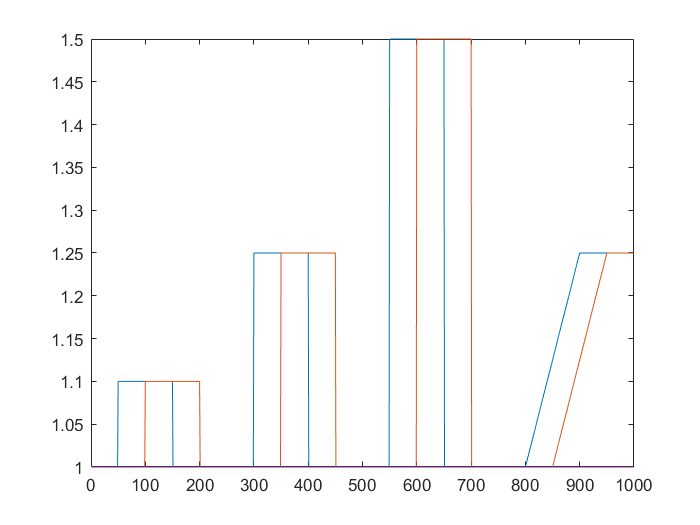

% Simulation
Ts = 1;
itmax = 1000;
t = 0:Ts:itmax*Ts;
% Deviation (from input steady state)
deviation = ones(4,length(t));
deviation(1,itmax*0.05:itmax*0.15) = 1.1;
deviation(1,itmax*0.3:itmax*0.4) = 1.25;
deviation(1,itmax*0.55:itmax*0.65) = 1.5;
deviation(1,itmax*0.8:itmax*0.9) = linspace(1,1.25,itmax*0.1+1);
deviation(1,itmax*0.9:end) = 1.25;
deviation(2,itmax*0.1:itmax*0.2) = 1.1;
deviation(2,itmax*0.35:itmax*0.45) = 1.25;
deviation(2,itmax*0.6:itmax*0.7) = 1.5;
deviation(2,itmax*0.85:itmax*0.95) = linspace(1,1.25,itmax*0.1+1);
deviation(2,itmax*0.95:end) = 1.25;
plot(deviation')
xlim([0 itmax])

for it = 1:length(t)-1
    fts_det.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
end

Now the results are plotted being nonnormalized and normalized:

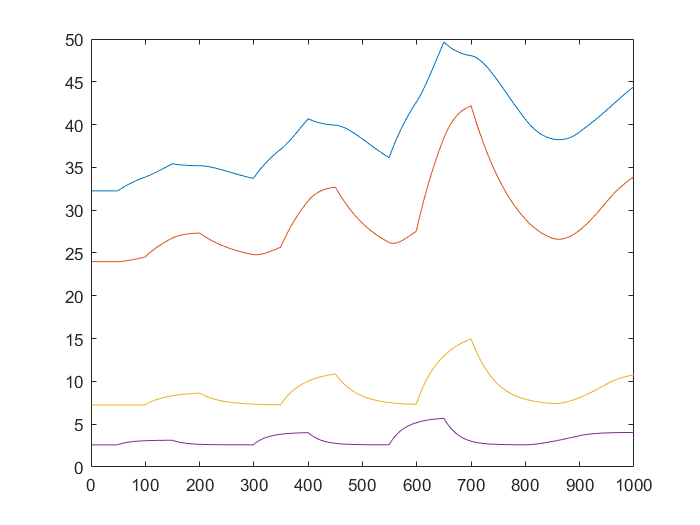

% Plot
plot(fts_det.record.meas)

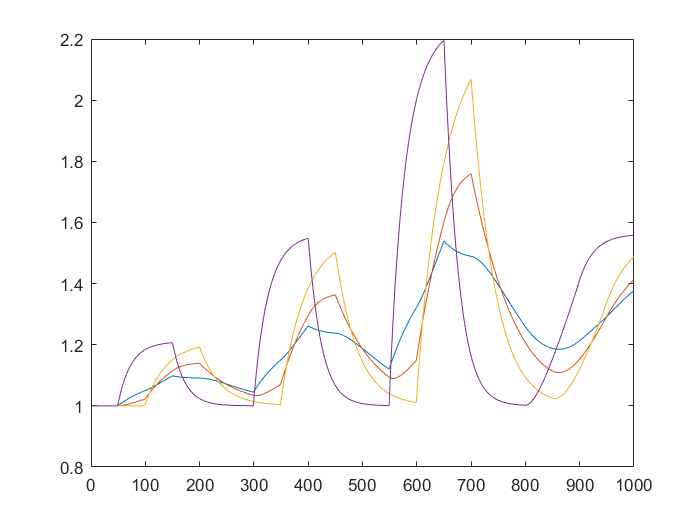

% Normalized plot
plot(fts_det.record.meas./fts_det.hs')

## Question 3.2-3

Now we duplicate the original instance to the noisy ones:

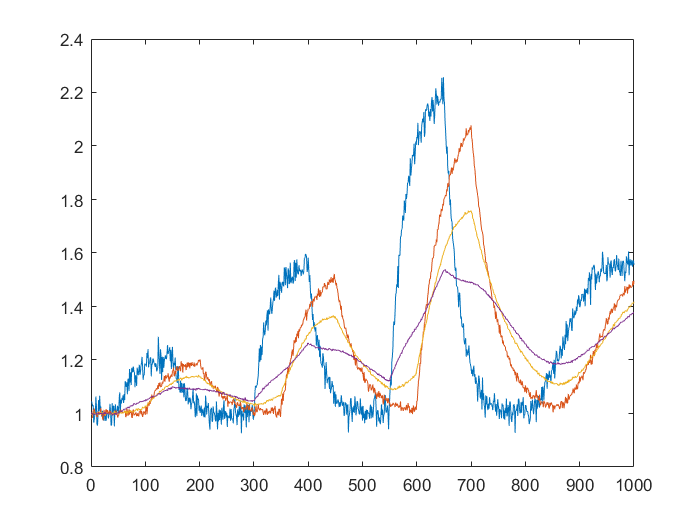

% Start from zero again
fts_det.reinitialize()
fts_vlow = copy(fts_det);
fts_vmedium = copy(fts_det);
fts_vhigh = copy(fts_det);
% Initializing the noise
noise.Rww = zeros(4);
noise.Rvv = 0.005*eye(4);
fts_vlow.addnoise(noise)
noise.Rvv = 0.02*eye(4);
fts_vmedium.addnoise(noise)
noise.Rvv = 0.1*eye(4);
fts_vhigh.addnoise(noise)
% Simulation including noise
for it = 1:length(t)-1
    fts_vlow.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
    fts_vmedium.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
    fts_vhigh.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
end
% Plots of the noise corrupted measurements:
plot(flip((fts_vlow.record.meas)./fts_vlow.hs',2))

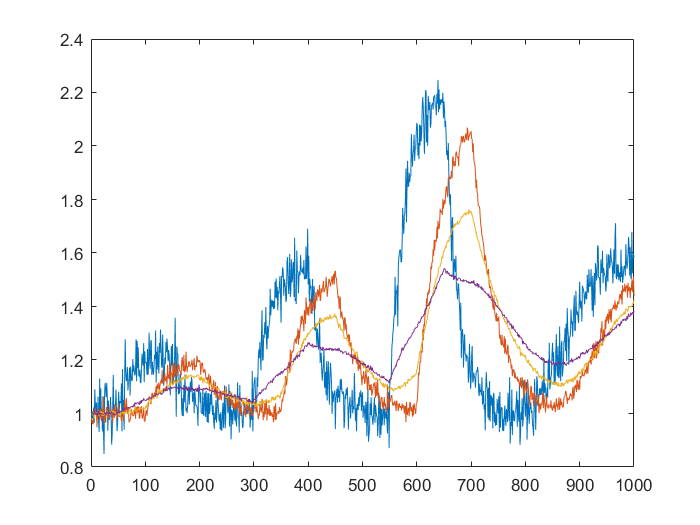

plot(flip((fts_vmedium.record.meas)./fts_vmedium.hs',2))

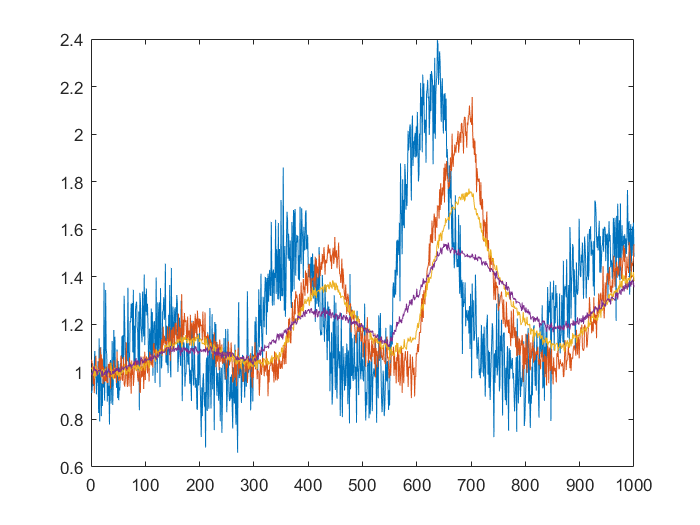

plot(flip((fts_vhigh.record.meas)./fts_vhigh.hs',2))

Note that the plots are now in opposite order to show the lines simulatenously better (this is not advantageous in colour for the whole document TODO)

## Question 3.5-8 TODO

# Problem 4 - Linearization and discretization

## Question 4.1

TODO: THEORY

After the Taylor expansion (for the order of one) we get the following state space matrices around the steady state point:


$$\mathbf{A} = \pmatrix{-\frac{1}{T_1} & 0 & -\frac{1}{T_3} & 0 \cr 0 & -\frac{1}{T_2} & 0 & -\frac{1}{T_4} \cr 0 & 0 & -\frac{1}{T_3} & 0 \cr 0 & 0 & 0 -\frac{1}{T_4}}$$



$$T_i = \sqrt{\frac{2 A m_{s,i}}{\rho g}}\frac{1}{a}$$



$$\mathbf{B} = \pmatrix{\rho \gamma_1 & 0 \cr 0 & \rho \gamma_2 \cr  0 & \rho (1-\gamma_2) \cr \rho (1-\gamma_2) & 0 }$$



$$\mathbf{C} = \pmatrix{\frac{1}{\rho A_1} & 0 & 0 & 0 \cr 0 & \frac{1}{\rho A_2} & 0 & 0 \cr 0 & 0 & \frac{1}{\rho A_3} & 0 \cr 0 & 0 & 0 & \frac{1}{\rho A_4}}$$



$$\mathbf{C_z} = \pmatrix{\frac{1}{\rho A_1} & 0 & 0 & 0 \cr 0 & \frac{1}{\rho A_2} & 0 & 0 }$$


The disturbances can be both steps and Brownian motion. The measurement noise is also Brownian motion. Therefore the matrix G is made up of the disturbance matrices leading the former, and latter effects into the dynamics.


$$\mathbf{G}_{mean} = \pmatrix{\mathbf{0} \cr  \rho \mathbf{I} }_{2x4}$$



$$\mathbf{G}_{variance} = \pmatrix{ \mathbf{0} \cr   \rho \mathbf{I}\sqrt{\mathbf{Q}}_L }_{2x4}$$


Where the square root denotes the lower triangular square root matrix. The second matrix is necessary, when the discretization is carried out, since in that case the formulae assume standard Gaussian noise as input. Fortunately, the mean and the variance can be treated independently.

The continuous time linearized state space models for the three models from Problem 2: 

% Create the object with noisy disturbance
fts = copy(fts_det);

Only the last two states are corrupted by noise.

% Noises
noise.Rww = diag([0 0 1e0 1e0]);
noise.Rvv = 0.005*eye(4);
fts.addnoise(noise)
% Analytically linearize the system
fts.linearize
% Plot the system matrices
fts.ssc

ans = struct with fields:
      A: [4×4 double]
      B: [4×2 double]
      G: [4×2 double]
      C: [4×4 double]
     Cz: [2×4 double]
    Rww: [4×4 double]
    Rvv: [4×4 double]
    Rwv: [4×4 double]


## Question 4.2 TODO

The zero-pole-gain form transfer functions are the following:

% Zero-pole-gain form of the continuous transfer function
%zpk(fts.tfc)

We can see that certain poles appear in more transfer functions. Since leading the fluid through one extra tank just gives extra dynamics but does not change the earlier, the dynamics leading to the same measurements share poles for different inputs.

## Question 4.3

The general (polynomial) form of the continuous transfer functions are the following:

% Polynomial forms of the continuous transfer functions
%fts.tfc

## Question 4.4

Compare to the identification from Problem 3 TODO

## Question 4.5

For an easy interpretation choice, the chosen sampling time is 1 second. In this case, the discrete state space model is:

% Chosen sampling time
Ts = 1;
% Discretization
fts.discretize(Ts)
% Converting the state space system to discrete
fts.ssd

ans = struct with fields:
      A: [4×4 double]
      B: [4×2 double]
      G: [4×4 double]
      C: [4×4 double]
     Cz: [2×4 double]
    Rww: [4×4 double]
    Rvv: [4×4 double]
    Rwv: [4×4 double]
     Ts: 1


## Question 4.6-7 TODO

Since the code for calculating the Markov parameters is embedded into a Kalman filter object, we are going to first initialize the Kalman filter.

% Sharing the linearized state space model
system = fts.ssd;
noise.R = system.Rvv;
noise.Q = system.Rww;
noise.S = system.Rwv;
% Initials
initial.x = zeros(4,1);
initial.P = eye(4);
% Making an instance the Kalman Filter object
kf_stat = KalmanFilter;
% Stationary Kalman Filter
kfType = 'stationary';
horizon = 1;
kf_stat.initialize(system,noise,initial,kfType,horizon);

The Markov parameters are calculated then:

% The Markov parameters
kf_stat.Markov

ans =     0.0017    0.0000
    0.0000    0.0014


# Problem 5

## Question 5.1

TODO, connect with results of identification

If we do not significantly deviate from the chosen linearisation point, the error that we commit during estimation is negligible (this is the basic motivation of using Taylor series).

If we have a constant sampling time, then the way of connecting the instants of a linear system is multiplying by $e^{A(t-t_0)}=e^{AT_s}=A_d$, and $B_d$ can be deduced from


$$\pmatrix{A_d & B_d \cr 0 & I} = \exp{\pmatrix{A & B \cr 0 & 0}T_s}$$


## Question 5.2

The initialization of the stationary Kalman filter object is already done for deducing the Markov parameters. The initialization of the dynamic Kalman filter:

kf_dyn = KalmanFilter;
% Dynamic Kalman Filter
kfType = 'timeinvariant';
kf_dyn.initialize(system,noise,initial,kfType,horizon);

The simulation is done for both of the filters:

% Reinitialization
fts.reinitialize();
initial.x = ones(4,1)*1e3;
initial.P = eye(4)*1e3;
kf_stat.reinitialize(initial,horizon);
kf_dyn.reinitialize(initial,horizon);
% Declaration of the estimation vectors
xf_stat = zeros(4,length(t)-1);
xf_dyn = zeros(4,length(t)-1);
% Simulation with Kalman estimators
for it = 1:length(t)-1
    fts.timestep([t(it); t(it+1)],ssInput.*deviation(:,it));
    y = fts.record.meas(end,:)' - fts_vlow.hs;
    u = ssInput.*(deviation(:,it) - 1);
    xf_stat(:,it) = kf_stat.outputPredictor(u(1:2,1),y,noise.Q,horizon);
    xf_dyn(:,it) = kf_dyn.outputPredictor(u(1:2,1),y,noise.Q,horizon);
end
% Plots of the noise corrupted measurements:
subplot(411)
plot(fts.record.t,fts.record.x(:,1)-fts.ms(1))
hold on
plot(xf_stat(1,:)')
plot(xf_dyn(1,:)')
hold off
subplot(412)
plot(fts.record.t,fts.record.x(:,2)-fts.ms(2))
hold on
plot(xf_stat(2,:)')
plot(xf_dyn(2,:)')
hold off
subplot(413)
plot(fts.record.t,fts.record.x(:,3)-fts.ms(3))
hold on
plot(xf_stat(3,:)')
plot(xf_dyn(3,:)')
hold off
subplot(414)
plot(fts.record.t,fts.record.x(:,4)-fts.ms(4))
hold on
plot(xf_stat(4,:)')
plot(xf_dyn(4,:)')
hold off

## Question 5.3

Since the Kalman Filter should not have knowledge of the disturbance until it is augmented, the estimator object will not receive the same inputs as the true plant.

% Reinitialization
fts.reinitialize();
initial.x = ones(4,1)*1e3;
initial.P = eye(4)*1e3;
kf_stat.reinitialize(initial,horizon);
kf_dyn.reinitialize(initial,horizon);
% Declaration of the estimation vectors
xf_stat = zeros(4,length(t)-1);
xf_dyn = zeros(4,length(t)-1);

As there is a step input for the disturbances, we change the variable ssInput. Let us say that it is a pulse, having the same effect on both tanks (for example modelling raining with open tanks). We assume no deviation in the original inputs from steady state, so the effect of the disturbance can be investigated independently.

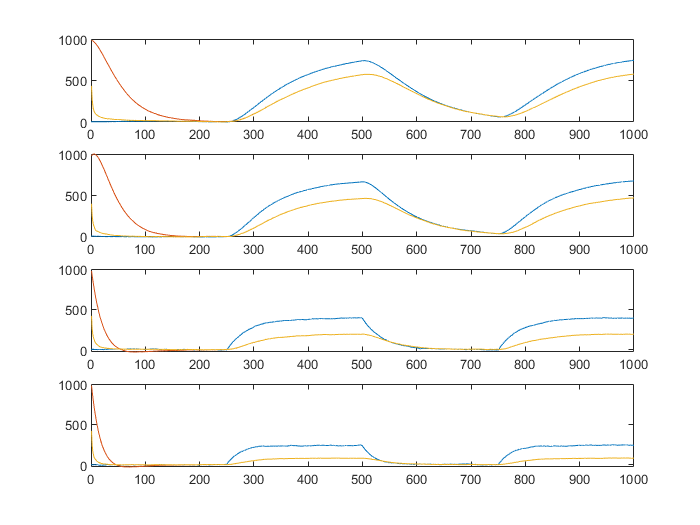

% Disturbance base creation
ssInput(3:4,:) = [10; 10];
% Time evolution of disturbance
deviation_dist = deviation;
deviation_dist(:,:) = 1;
deviation_dist(3:4,1:itmax/4) = 0;
deviation_dist(3:4,itmax/2:itmax/4*3) = 0;
plot(deviation_dist')
xlim([1 length(t)])
% Simulation with Kalman estimators
for it = 1:length(t)-1
    fts.timestep([t(it); t(it+1)],ssInput.*deviation_dist(:,it));
    y = fts.record.meas(end,:)' - fts_vlow.hs;
    u = ssInput.*(deviation_dist(:,it) - 1);
    xf_stat(:,it) = kf_stat.outputPredictor(u(1:2,1),y,noise.Q,horizon);
    xf_dyn(:,it) = kf_dyn.outputPredictor(u(1:2,1),y,noise.Q,horizon);
end
% Plots of the noise corrupted measurements:
subplot(411)
plot(fts.record.t,fts.record.x(:,1)-fts.ms(1))
hold on
plot(xf_stat(1,:)')
plot(xf_dyn(1,:)')
hold off
subplot(412)
plot(fts.record.t,fts.record.x(:,2)-fts.ms(2))
hold on
plot(xf_stat(2,:)')
plot(xf_dyn(2,:)')
hold off
subplot(413)
plot(fts.record.t,fts.record.x(:,3)-fts.ms(3))
hold on
plot(xf_stat(3,:)')
plot(xf_dyn(3,:)')
hold off
subplot(414)
plot(fts.record.t,fts.record.x(:,4)-fts.ms(4))
hold on
plot(xf_stat(4,:)')
plot(xf_dyn(4,:)')
hold off

If we augment the estimators, being prepared for (knows about) the disturbance, the estimation will not have steady state errors anymore. Since we do not know the input, we try to estimate them with assuming hidden states:


$$\pmatrix{\mathbf{\dot{x}} \cr \mathbf{\dot{x}_d}} = \pmatrix{\mathbf{A} & \mathbf{G} \cr \mathbf{0} & \mathbf{0}}\pmatrix{\mathbf{x} \cr \mathbf{x}_d}+\pmatrix{\mathbf{0} \cr \mathbf{I}}\mathbf{d}$$


% Augmented system, continuous
system_aug_cont.A = [fts.ssc.A fts.ssc.G; zeros(2,4) zeros(2)];
system_aug_cont.B = [system.B; zeros(2)];
system_aug_cont.C = [system.C zeros(4,2)];
system_aug_cont.G = [zeros(4,2); eye(2)];
system_aug_cont.Cz = [system.Cz zeros(2)];
system_aug_cont.Rww = diag([0; 0; diag(fts.ssc.Rww)]);
system_aug_cont.Rwv = [fts.ssc.Rwv; zeros(2,4)];
system_aug_cont.Rvv = fts.ssc.Rvv;
% Augmented system, discrete
system_aug = system_aug_cont;
[Ad,Bd] = c2d(system_aug_cont.A,system_aug_cont.B,Ts);
system_aug.A = Ad;
system_aug.B = Bd;
system_aug.G = eye(6);
system_aug.Rww = fts.c2d_noise(system_aug_cont.A,system_aug_cont.G*fts.Lrww(3:4,3:4),Ts);

The discrete time Riccati equation cannot be solved (at least not correctly), if there are states with no variance, since the following has to hold for the subsystem of states unaffected by other states:


$$\pmatrix{\textbf{GQG'} & \textbf{S} \cr \textbf{S'} & \textbf{R}}>0$$


Therefore the whole system had to be rephrased so that the noise arrives through the disturbance, and is not independent of the deterministic part.

**It is not applied now: **With empirical tuning, the right variances, with other words, distrust factors can be set for a good estimator convergence:

noise_aug.R = system_aug.Rvv;
% Theoretical Q matrix
noise_aug.Q = system_aug.Rww;
% Practical modification to solve dare
%disturbanceDistrust = 1;
%noise_aug.Q(5:6,5:6) = eye(2)*disturbanceDistrust;
noise_aug.S = system_aug.Rwv;
% Augmented Kalman Filter instance
kf_aug = KalmanFilter;
% Stationary Kalman Filter
kfType = 'stationary';
initial.x = ones(6,1);
initial.P = eye(6)*1e3;
kf_aug.initialize(system_aug,noise_aug,initial,kfType,horizon);

Reinitialization and simulation with plots: 

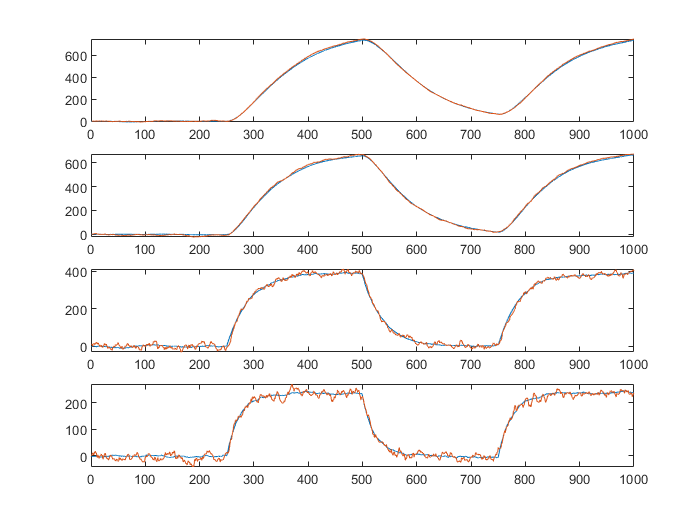

% Reinitialization
fts.reinitialize();
% Declaration of the estimation vectors
xf_aug = zeros(6,length(t)-1);
% Simulation with Kalman estimators
for it = 1:length(t)-1
    fts.timestep([t(it); t(it+1)],ssInput.*deviation_dist(:,it));
    y = fts.record.meas(end,:)' - fts_vlow.hs;
    u = ssInput.*(deviation_dist(:,it) - 1);
    xf_aug(:,it) = kf_aug.outputPredictor(u(1:2,1),y,noise_aug.Q,horizon);
end
% Plots of the noise corrupted measurements:
subplot(411)
plot(fts.record.t,fts.record.x(:,1)-fts.ms(1))
hold on
plot(xf_aug(1,:)')
hold off
subplot(412)
plot(fts.record.t,fts.record.x(:,2)-fts.ms(2))
hold on
plot(xf_aug(2,:)')
hold off
subplot(413)
plot(fts.record.t,fts.record.x(:,3)-fts.ms(3))
hold on
plot(xf_aug(3,:)')
hold off
subplot(414)
plot(fts.record.t,fts.record.x(:,4)-fts.ms(4))
hold on
plot(xf_aug(4,:)')
hold off

Plotting the disturbances:

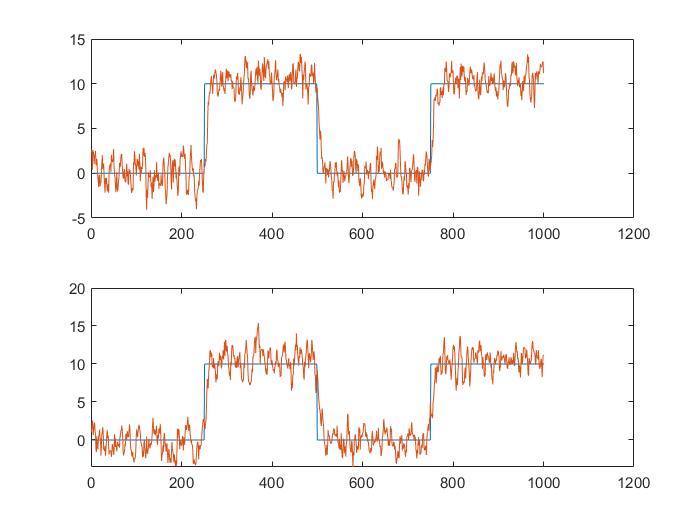

% Plotting the disturbances
figure
subplot(211)
plot(ssInput(3)*deviation_dist(3,:))
hold on
plot(xf_aug(5,:)')
hold off
xlim([0 length(t)-1])
subplot(212)
plot(ssInput(4)*deviation_dist(4,:))
hold on
plot(xf_aug(6,:)')
hold off

xlim([0 length(t)-1])

## Question 5.4

Note that there is no need for linear simulation: the Kalman filter would have the same behaviour far away from the linearization point as being close to that. 

As we can see the Kalman filter has better performance, if the model is close to the plant; we have to be close to the linearization point (else steady state error can be expected due to the disturbance-like appearance of the deviation), and we have to model nonzero mean disturbances that propagate throught the system. If the latter are not modelled, we can see in the first plots, that the estimation is a trade off between the model and the innovation; the weights decide, what it is going to be closer. In case of the modelling of the disturbance, the uncertainty of the modelled part of the system increases, and the estimator relies more on the innovation. This ends up with noisier estimations, which are, in the end, closer to the true values in the mean.

The disturbances were also successfully estimated.

# Problem 6 - Unconstrained MPC

## Question 6.1

Describe how mpc works and theoretical background TODO.

## Question 6.2

Design of Model Predictive Controller.

The chosen horizon is 60 seconds, since this is a slow system. Generally the bigger the horizon was, the better results we got, but the computation time increased significantly as well.

% Reinitialize Kalman Filter with the prediction horizon
horizon = 60;
kf_aug.reinitialize(initial,horizon);
% Creating instance
mpc = ModelPredictiveController;

Preinitialization is necessary to determine the dimensions of the controller. For special instances, the preinitialized object instance is copied.

% Preinitialization
n = kf_aug.stateSpaceDimensions();
mpc.preinitialize(horizon,n);

Creation of unconstrained controller.

% Creation of the copy
mpc_unconstrained = copy(mpc);
% Number of objectives
n.no = 2;
n.nscl = 0;
n.nscu = 0;
% Initialization of weights and coefficients of objective functions
W = cell(2,1);
Ucoeff = cell(2,1);
% Unconstrained MPC
ExtraFeatures.useInputConstraints = false;
ExtraFeatures.useInputRateConstraints = false;
ExtraFeatures.useSoftOutputConstraints = false;
% Weight on output
W{1} = diag([1e2 1e2]);
% Weight on input (control signal)
W{2} = diag([1 1]);

The objectives are chosen to be identical to the finite horizon LQR controller problem: the reference tracking error and the input deviation from the steady state input are minimized.

% Objective phrasing
Ucoeff{1} = kf_aug.Markov;
Ucoeff{2} = kron(eye(n.nu),eye(horizon));
% Initial input signal
u_1 = zeros(2,1);
% Algorithm used in case of constrained optimization
optioptions.Algorithm = 'interior-point-convex';
optioptions.Display = 'off';
mpc_unconstrained.initialize(W,Ucoeff,n,ExtraFeatures,u_1,optioptions)

## Question 6.3

% Reinitialization - KF is already reinitialized
fts.reinitialize();
% Constant of second objective function
c = cell(2,1);
% The initial input vector
U = kron(zeros(horizon,1),ones(n.nu,1));
% Initial measurement
y = zeros(4,1);

The required reference signal is a pulse function with period itmax/5:

% Reference signal
reference = diag([fts.hs(1:2,1)/100])*diag([1 -0.5])

reference =     0.3226         0
         0   -0.1200


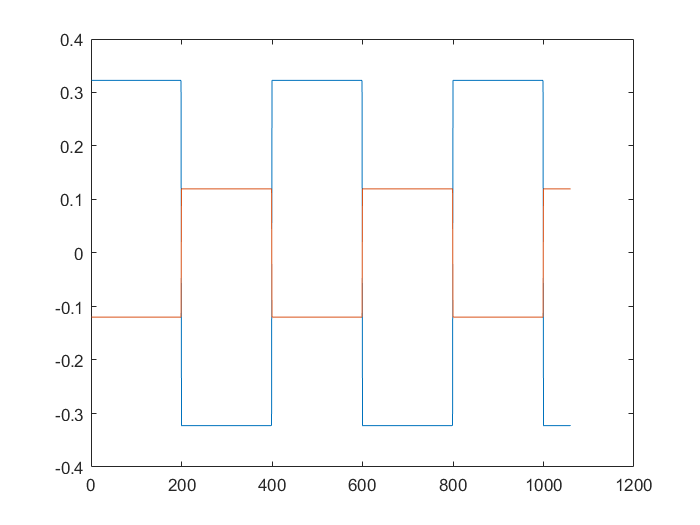

R = reference*ones(2,length(t)-1+horizon);
for it = 1:length(t)-1+horizon
    if rem(floor(it/(itmax/5)),2)
        R(:,it) = -R(:,it);
    end
end
figure
plot(R')

xlim([0 length(t)-1])

Only plotted bounds for later comparison:

% Plotted bounds
heightBounds = [0.33; 0.2]

heightBounds =     0.3300
    0.2000


Simulation of estimation based control, having disturbance:

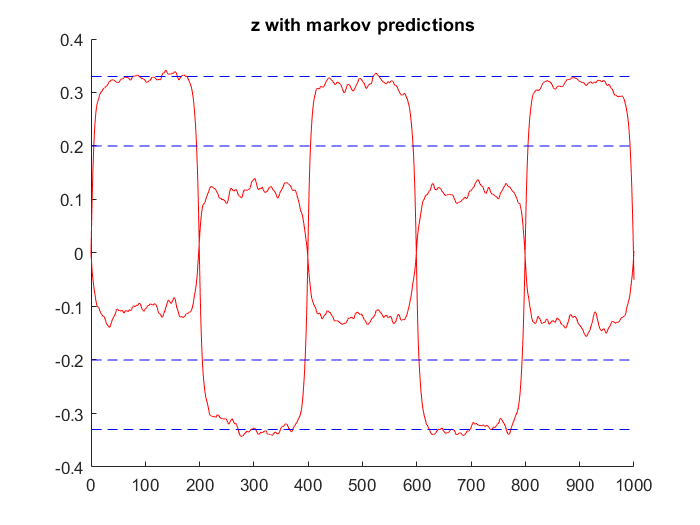

% Declaration of record
record.u = zeros(n.nu,length(t)-1);
figure
clf
hold on
for it = 1:length(t)-1
    % Kalman Filter, Markov predictor
    kf_aug.markovPredictor(U,y);
    % Model Predictive Control
    Z = reshape(R(:,it:it+horizon-1),kf_aug.nu*kf_aug.j,1);
    % kron(ones(horizon,1),ones(kf_aug.nu,1)); % TODO
    c{1} = Z-kf_aug.b;
    c{2} = kron(zeros(horizon,1),ones(2,1));
    ExtraFeatures.b = kf_aug.b;
    [u, U] = mpc_unconstrained.controlCompute(c,ExtraFeatures);
    % Physical system and measurement
    fts.timestep([t(it); t(it+1)],ssInput.*deviation_dist(:,it)+[u; zeros(2,1)]);
    y = fts.record.meas(end,:)' - fts_vlow.hs;
    % Print prediction
    %plot(it*Ts:Ts:(it-1+kf_aug.j)*Ts,kf_aug.zj(1:2:end),'k')
    %plot(it*Ts:Ts:(it-1+kf_aug.j)*Ts,kf_aug.zj(2:2:end),'k')
    % Saving input
    record.u(1:kf_aug.nz,it) = u;
end
plot(fts.record.t,fts.record.x(:,1:2)/fts.rho/fts.A-fts.hs(1:2)','r')
plot(heightBounds(1)*ones(itmax,1),'--b')
plot(-heightBounds(1)*ones(itmax,1),'--b')
plot(heightBounds(2)*ones(itmax,1),'--b')
plot(-heightBounds(2)*ones(itmax,1),'--b')
hold off
xlabel('Time [seconds]')

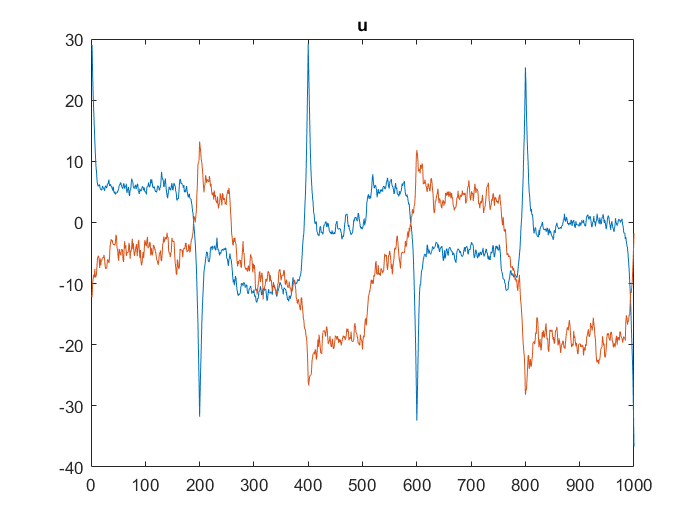

figure
plot(record.u')
xlabel('Time [seconds]')

# Problem 7 - Input Constrained MPC

## Question 7.1

Theory -TODO

## Question 7.2

The same objects is used to create the input constrained MPC.

## Question 7.3

The usage is the following. Apart from the input constraint, input rate constraint is used as well.

% Creation of the copy
mpc_inputConstrained = copy(mpc);
% Number of objectives
n.no = 3;
% Initialization of weights and coefficients of objective functions
W = cell(3,1);
Ucoeff = cell(3,1);
% Input cconstrained MPC
ExtraFeatures.useInputConstraints = true;
ExtraFeatures.useInputRateConstraints = true;
% Weight on output, input, input rate
W{1} = diag([1e2 1e2]);
W{2} = diag([1 1]);
W{3} = diag([1e-2 1e-2]);
% Objective phrasing
Ucoeff{1} = kf_aug.Markov;
Ucoeff{2} = kron(eye(n.nu),eye(horizon));
Ucoeff{3} = mpc.Lambda;
% Initial input signal
mpc_inputConstrained.initialize(W,Ucoeff,n,ExtraFeatures,u_1,optioptions);
% Reinitialization
fts.reinitialize();
kf_aug.reinitialize(initial,horizon);
% Constant of second objective function
c = cell(3,1);
% Algorithm used in case of constrained optimization
optioptions.Algorithm = 'interior-point-convex';
% The initial input vector and measurement
U = kron(zeros(horizon,1),ones(n.nu,1));
y = zeros(4,1);
% Declaration of record
record.u = zeros(n.nu,length(t)-1);

Here are the bounds declared:

ExtraFeatures.Bounds.Umin = -10*ones(horizon*kf_aug.nu,1);
ExtraFeatures.Bounds.Umax = 10*ones(horizon*kf_aug.nu,1);
ExtraFeatures.Bounds.DUmin = -100*ones(horizon*kf_aug.nu,1); 
ExtraFeatures.Bounds.DUmax = 100*ones(horizon*kf_aug.nu,1);

Then the simulation:

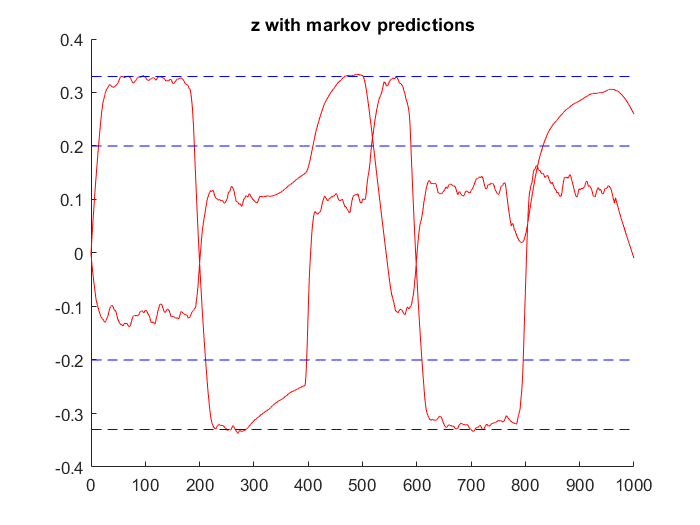

clf
hold on
for it = 1:length(t)-1
    % Kalman Filter, Markov predictor
    kf_aug.markovPredictor(U,y);
    % Model Predictive Control
    Z = reshape(R(:,it:it+horizon-1),kf_aug.nu*kf_aug.j,1);
    c{1} = Z-kf_aug.b;
    c{2} = kron(zeros(horizon,1),ones(2,1));
    c{3} = mpc_inputConstrained.I0*mpc_inputConstrained.u_1;
    ExtraFeatures.b = kf_aug.b;
    [u, U] = mpc_inputConstrained.controlCompute(c,ExtraFeatures);
    % Physical system and measurement
    fts.timestep([t(it); t(it+1)],ssInput.*deviation_dist(:,it)+[u; zeros(2,1)]);
    y = fts.record.meas(end,:)' - fts_vlow.hs;
    % Print prediction
    %plot(it*Ts:Ts:(it-1+kf_aug.j)*Ts,kf_aug.zj(1:2:end),'k')
    %plot(it*Ts:Ts:(it-1+kf_aug.j)*Ts,kf_aug.zj(2:2:end),'k')
    % Saving input
    record.u(1:kf_aug.nz,it) = u;
end
plot(fts.record.t,fts.record.x(:,1:2)/fts.rho/fts.A-fts.hs(1:2)','r')
plot(heightBounds(1)*ones(itmax,1),'--b')
plot(-heightBounds(1)*ones(itmax,1),'--b')
plot(heightBounds(2)*ones(itmax,1),'--b')
plot(-heightBounds(2)*ones(itmax,1),'--b')
hold off
xlabel('Time [seconds]')

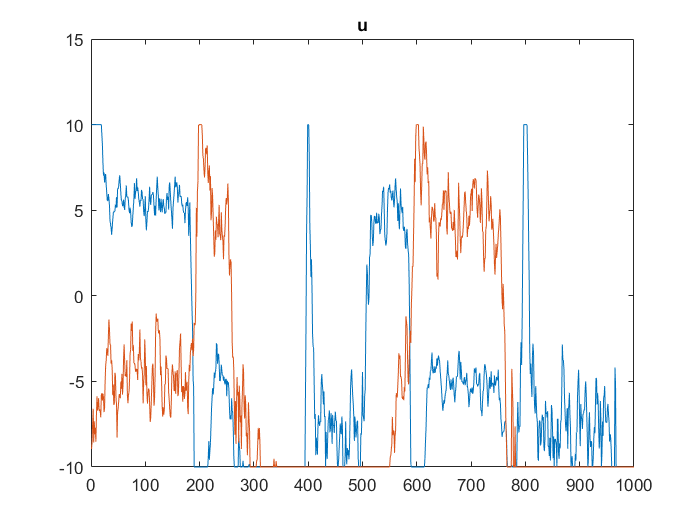

figure
plot(record.u')
xlabel('Time [seconds]')

We can see that with a certain input constraint, the controller is not able to fulfill its objectives when there is a disturbance affecting the system - as it becomes saturated.

# Problem 8 - MPC with input constrainst and soft output constraints

## Question 7.1

Theory -TODO

## Question 7.2

The same objects is used to create the input constrained and soft output constrained MPC.

## Question 7.3

The usage is the following. Apart from the input constraint, input rate constraint is used as well.

The computation time has significantly increased, and the optimization algorithm often got stuck, while struggling with the various constraints, and could not fulfill all of them. Therefore, to ease the challenge, the horizon is decreased.

% MPC with new horizon
horizon = 10;
kf_aug.reinitialize(initial,horizon);
mpc.preinitialize(horizon,n);
% Creation of the copy
mpc_ioC = copy(mpc);
% Number of objectives
n.nscl = 1;
n.nscu = 1;
% Initialization of weights and coefficients of objective functions
W = cell(5,1);
% Input and Soft-Output Constrained MPC
ExtraFeatures.useSoftOutputConstraints = true;
% Passing on the Markov matrix
ExtraFeatures.Markov = kf_aug.Markov;
% Weight on output, input, input rate
W{1} = diag([1e2 1e2]);     % Reference tracking
W{2} = diag([1 1]);         % Deviation from steady state input
W{3} = diag([1e-2 1e-2]);   % Input rate punishment
W{4} = diag([1e0 1e0]);     % Lower output constraint
W{5} = diag([1e0 1e0]);     % Higher output constraint
% Objective phrasing
Ucoeff{1} = kf_aug.Markov;
Ucoeff{2} = kron(eye(n.nu),eye(horizon));
Ucoeff{3} = mpc.Lambda;
% Initial input signal
mpc_ioC.initialize(W,Ucoeff,n,ExtraFeatures,u_1,optioptions);
% Reinitialization
fts.reinitialize();
kf_aug.reinitialize(initial,horizon);
% The initial input vector and measurement
U = kron(zeros(horizon,1),ones(n.nu,1));
y = zeros(4,1);
% Declaration of record
record.u = zeros(n.nu,length(t)-1);

The input constraints are not so restrictive anymore:

% Eased input constraints
ExtraFeatures.Bounds.Umin = -30*ones(horizon*kf_aug.nu,1);
ExtraFeatures.Bounds.Umax = 30*ones(horizon*kf_aug.nu,1);
ExtraFeatures.Bounds.DUmin = -300*ones(horizon*kf_aug.nu,1); 
ExtraFeatures.Bounds.DUmax = 300*ones(horizon*kf_aug.nu,1);

Then we declare the output constraints:

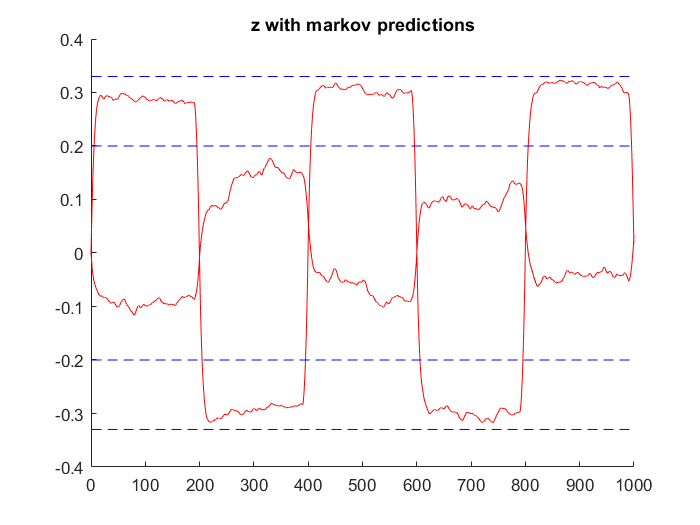

% Declaration 
ExtraFeatures.Bounds.Rmin = {-kron(ones(horizon,1),heightBounds)};
ExtraFeatures.Bounds.Rmax = {kron(ones(horizon,1),heightBounds)};
clf
hold on
for it = 1:length(t)-1
    % Kalman Filter, Markov predictor
    kf_aug.markovPredictor(U,y);
    % Model Predictive Control
    Z = reshape(R(:,it:it+horizon-1),kf_aug.nu*kf_aug.j,1);
    c{1} = Z-kf_aug.b;
    c{2} = kron(zeros(horizon,1),ones(2,1));
    c{3} = mpc_ioC.I0*mpc_ioC.u_1;
    ExtraFeatures.b = kf_aug.b;
    [u, U] = mpc_ioC.controlCompute(c,ExtraFeatures);
    % Physical system and measurement
    fts.timestep([t(it); t(it+1)],ssInput.*deviation_dist(:,it)+[u; zeros(2,1)]);
    y = fts.record.meas(end,:)' - fts_vlow.hs;
    % Print prediction
    %plot(it*Ts:Ts:(it-1+kf_aug.j)*Ts,kf_aug.zj(1:2:end),'k')
    %plot(it*Ts:Ts:(it-1+kf_aug.j)*Ts,kf_aug.zj(2:2:end),'k')
    % Saving input
    record.u(1:kf_aug.nz,it) = u;
end
plot(fts.record.t,fts.record.x(:,1:2)/fts.rho/fts.A-fts.hs(1:2)','r')
plot(heightBounds(1)*ones(itmax,1),'--b')
plot(-heightBounds(1)*ones(itmax,1),'--b')
plot(heightBounds(2)*ones(itmax,1),'--b')
plot(-heightBounds(2)*ones(itmax,1),'--b')
hold off
xlabel('Time [seconds]')

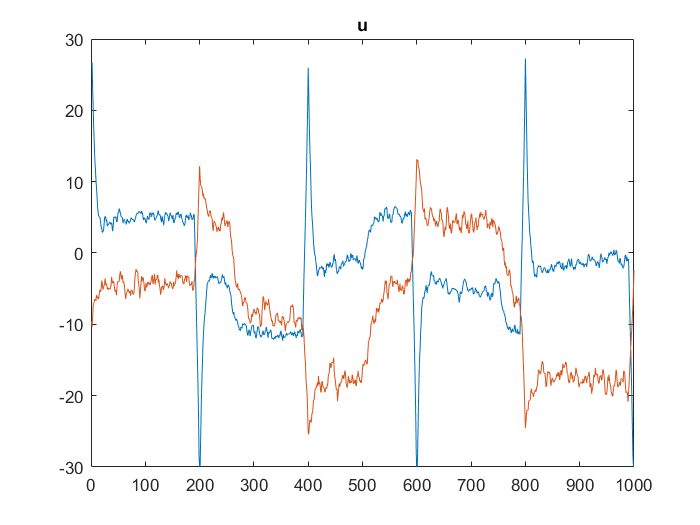

figure
plot(record.u')
xlabel('Time [seconds]')

Titles for the plots, and saves and references for some. Discussion of the iomplementation functions. TODO

We can see that finally the avoidance of extreme values can be avoided with soft output constraints (though this means small steady state error in the reference tracking, not only in the height that is close to a bound, but a pair of it). 

# Problem 9 - Closed Loop Simulations - TODO

# Problem 10 - Discussion and Conclusion